clear; clc; close all;

%% ============================
% 1) Key Radii, Lengths, and Angle Parameters
%% ============================

% Geometric Parameters
r_th   = 0.09;                  % Desired Throat Radius (minimum)
r_in   = 3 * r_th;          % Inlet radius 
% NOTE: r_C and r_D now only serve as the endpoints for the throat polynomial.
% They can be chosen independently, but the constrained throat function will force
% the minimum (at x = L_th/2) to be exactly r_th.
r_C    = r_th*2;                   % Radius at end of convergent (x = 0)
r_D    = r_th*2;                   % Radius at start of divergent (x = L_th)

A_ratio = 200;                   % Area ratio (Exit area / Throat area)
A_exit  = A_ratio * pi * r_th^2;   % Exit Area (based on throat area)
r_exit  = sqrt(A_exit/pi);         % Exit Radius

L_conv = 0.5;                    % Length of convergent section (m)
L_th   = 0.40;                   % Length of the throat region (m)
L_div  = 4.5;                    % Length of the divergent section (m)

% Angle parameters (in degrees)
convergent_exit_angle_deg = 30;    % Convergent exit angle (negative)
divergent_start_angle_deg   = 35;    % Divergent starting angle
divergent_exit_angle_deg    = 0;     % Divergent exit angle

% Convert angles to slopes43535250008
slope_conv_exit = -tan(deg2rad(convergent_exit_angle_deg));
slope_div_start = tan(deg2rad(divergent_start_angle_deg));
slope_div_exit  = tan(deg2rad(divergent_exit_angle_deg));

%% ============================
%% Convergent Section: (4th-degree Polynomial)
%% ============================
% The convergent is from x = -L_conv to x = 0.
[x_conv, y_conv, convPoly] = convergent_4th_poly(-L_conv, 0, r_in, r_C, slope_conv_exit);


--- Convergent 4th-degree Polynomial Equation ---
r(x) = 0.2700 + 0.0000x + 0.0000x^2 + -0.5706x^3 + -0.2988x^4



% Compute the curvature at x = 0 (end of convergent)
Lc = L_conv; % (x = 0 corresponds to X = L_conv in the polynomial)
a3 = convPoly.a3;
a4 = convPoly.a4;
curv_conv_exit = 6*a3*Lc + 12*a4*Lc^2;  % r''(0)

%% ============================
% (B) Throat: Constrained Throat using a 7th-Degree Polynomial
%% ============================
% We now define the throat for x in [0, L_th] with these conditions:
%   At x = 0:      r = r_C,           r' = slope_conv_exit,   r'' = curv_conv_exit.
%   At x = L_th/2:  r = r_th,          r' = 0.       (Enforcing the minimum exactly.)
%   At x = L_th:    r = r_D,           r' = slope_div_start,   r'' = 0.
[x_throat, y_throat, throatCoef] = constrained_throat_poly(0, L_th, r_C, slope_conv_exit, curv_conv_exit, r_D, slope_div_start, r_th);


--- Constrained Throat (7th-degree) Polynomial Equation ---
r(x) = 0.1800x^0 + -0.5774x^1 + -1.3041x^2 + 6.0646x^3 + 60.0743x^4 + -300.0327x^5 + 519.3539x^6 + -330.4299x^7 



%% ============================
% (C) Divergent Section: 5th-degree Rao Polynomial
%% ============================
% The divergent section is defined over x from L_th to L_th+L_div.
coef_div    = rao_5th_poly_customStart(r_D, slope_div_start, r_exit, L_div, slope_div_exit);


--- Divergent 5th-degree Rao Polynomial Equation ---
r(x) = 0.1800 + 0.7002x + 0.0000x^2 + -0.0875x^3 + 0.0215x^4 + -0.0016x^5


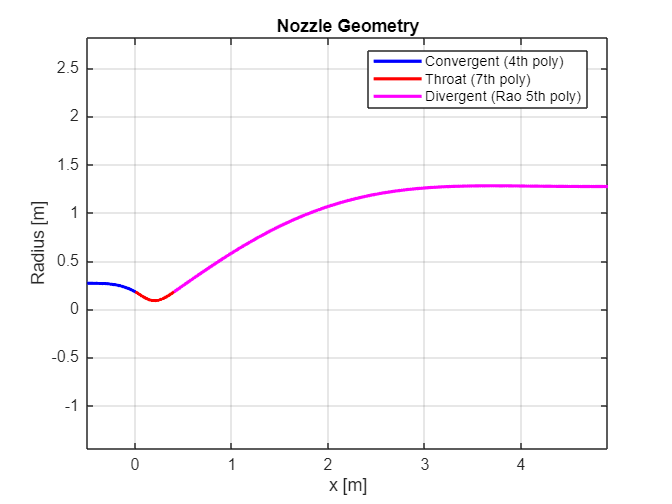

n_div       = 200;
s_div       = linspace(0, 1, n_div);
x_div_local = s_div * L_div;
y_div_local = evaluate_5th_poly(coef_div, x_div_local);
x_div       = x_div_local + L_th;  % shift to global x-coordinates
y_div       = y_div_local;

%% ============================
% Plot the Nozzle Geometry
%% ============================
figure('Name','Nozzle Geometry','Color','w');
hold on; grid on; box on;

plot(x_conv,   y_conv,   'b-', 'LineWidth',2, 'DisplayName','Convergent (4th poly)');
plot(x_throat, y_throat, 'r-', 'LineWidth',2, 'DisplayName','Throat (7th poly)');
plot(x_div,    y_div,    'm-', 'LineWidth',2, 'DisplayName','Divergent (Rao 5th poly)');

legend('Location','best');
xlabel('x [m]'); ylabel('Radius [m]');
title('Nozzle Geometry');
axis equal;


%% ============================
% Save Geometry Data to CSV and TXT Files
%% ============================
path_downloads = fullfile(getenv('USERPROFILE'), 'Downloads');
if ~exist(path_downloads, 'dir')
    mkdir(path_downloads);
end

% Prepare z-coordinates (zero for 2D extrusion)
z_conv   = zeros(size(x_conv));
z_throat = zeros(size(x_throat));
z_div    = zeros(size(x_div));

data_conv   = [x_conv(:),   y_conv(:),   z_conv(:)];
data_throat = [x_throat(:), y_throat(:), z_throat(:)];
data_div    = [x_div(:),    y_div(:),    z_div(:)];

% Save CSV files
writematrix(data_conv, fullfile(path_downloads, 'convergent_section_BC_Rao.csv'), 'Delimiter', ',');
writematrix(data_throat, fullfile(path_downloads, 'throat_section_BC_Rao.csv'), 'Delimiter', ',');
writematrix(data_div, fullfile(path_downloads, 'divergent_section_BC_Rao.csv'), 'Delimiter', ',');

% Save TXT files (for SolidWorks compatibility)
save(fullfile(path_downloads, 'convergent_section_BC_Rao.txt'), 'data_conv', '-ascii', '-double', '-tabs');
save(fullfile(path_downloads, 'throat_section_BC_Rao.txt'), 'data_throat', '-ascii', '-double', '-tabs');
save(fullfile(path_downloads, 'divergent_section_BC_Rao.txt'), 'data_div', '-ascii', '-double', '-tabs');

disp('Saved to Downloads:');

Saved to Downloads:


disp('CSV Files: convergent_section_BC_Rao.csv, throat_section_BC_Rao.csv, divergent_section_BC_Rao.csv');

CSV Files: convergent_section_BC_Rao.csv, throat_section_BC_Rao.csv, divergent_section_BC_Rao.csv


disp('TXT Files: convergent_section_BC_Rao.txt, throat_section_BC_Rao.txt, divergent_section_BC_Rao.txt');

TXT Files: convergent_section_BC_Rao.txt, throat_section_BC_Rao.txt, divergent_section_BC_Rao.txt



%% ============================
% Function Definitions
%% ============================

function [xvals, yvals, polyStruct] = convergent_4th_poly(xA, xB, r_in, rC, slope_exit)
    % Constructs a 4th-degree polynomial for the convergent section.
    L = xB - xA;
    a0 = r_in;
    a1 = 0;
    a2 = 0;
    
    % At x = xB:
    RHS1 = rC - a0;
    RHS2 = slope_exit - a1;
    A = [L^3, L^4; 3*L^2, 4*L^3];
    sol = A \ [RHS1; RHS2];
    a3 = sol(1);
    a4 = sol(2);
    
    npts = 100;
    xvals = linspace(xA, xB, npts);
    X = xvals - xA;
    yvals = a0 + a1*X + a2*X.^2 + a3*X.^3 + a4*X.^4;
    
    polyStruct.a0 = a0;
    polyStruct.a1 = a1;
    polyStruct.a2 = a2;
    polyStruct.a3 = a3;
    polyStruct.a4 = a4;
    
    fprintf('\n--- Convergent 4th-degree Polynomial Equation ---\n');
    fprintf('r(x) = %.4f + %.4fx + %.4fx^2 + %.4fx^3 + %.4fx^4\n', a0, a1, a2, a3, a4);
end

function [xvals, yvals, coef] = constrained_throat_poly(xA, xB, rA, slopeA, curvA, rB, slopeB, r_min)
    % Constructs a 7th-degree polynomial for the throat section with three sets of constraints:
    % At x = xA (start of throat):
    %     r = rA,    r' = slopeA,    r'' = curvA.
    % At x = xB (end of throat):
    %     r = rB,    r' = slopeB,    r'' = 0.
    % At x = (xA+xB)/2 (midpoint of throat):
    %     r = r_min, r' = 0.
    % For simplicity, we assume xA = 0.
    
    L = xB - xA;  % throat length
    % Known coefficients from x = 0:
    c0 = rA;
    c1 = slopeA;
    c2 = curvA/2;
    
    % Unknown coefficients: c3, c4, c5, c6, c7 for a 7th-degree polynomial:
    % r(x) = c0 + c1*x + c2*x^2 + c3*x^3 + c4*x^4 + c5*x^5 + c6*x^6 + c7*x^7.
    % Set up the following 5 equations:
    % (1) At x = L: r(L) = rB.
    % (2) At x = L: r'(L) = slopeB.
    % (3) At x = L: r''(L) = 0.
    % (4) At x = L/2: r(L/2) = r_min.
    % (5) At x = L/2: r'(L/2) = 0.
    
    % Write these in terms of c3...c7:
    % Equation (1):
    %   c3*L^3 + c4*L^4 + c5*L^5 + c6*L^6 + c7*L^7 = rB - (c0 + c1*L + c2*L^2).
    % Equation (2):
    %   3*c3*L^2 + 4*c4*L^3 + 5*c5*L^4 + 6*c6*L^5 + 7*c7*L^6 = slopeB - (c1 + 2*c2*L).
    % Equation (3):
    %   6*c3*L + 12*c4*L^2 + 20*c5*L^3 + 30*c6*L^4 + 42*c7*L^5 = -2*c2.
    % Equation (4): At x = L/2:
    %   c3*(L/2)^3 + c4*(L/2)^4 + c5*(L/2)^5 + c6*(L/2)^6 + c7*(L/2)^7 = r_min - (c0 + c1*(L/2) + c2*(L/2)^2).
    % Equation (5): At x = L/2:
    %   3*c3*(L/2)^2 + 4*c4*(L/2)^3 + 5*c5*(L/2)^4 + 6*c6*(L/2)^5 + 7*c7*(L/2)^6 = - (c1 + 2*c2*(L/2)).
    
    M = [ L^3,      L^4,       L^5,        L^6,         L^7;
          3*L^2,    4*L^3,     5*L^4,      6*L^5,       7*L^6;
          6*L,     12*L^2,    20*L^3,     30*L^4,      42*L^5;
          (L/2)^3, (L/2)^4,   (L/2)^5,    (L/2)^6,     (L/2)^7;
          3*(L/2)^2, 4*(L/2)^3, 5*(L/2)^4, 6*(L/2)^5, 7*(L/2)^6];
      
    b = [ rB - (c0 + c1*L + c2*L^2);
          slopeB - (c1 + 2*c2*L);
          -2*c2;
          r_min - (c0 + c1*(L/2) + c2*(L/2)^2);
          - (c1 + 2*c2*(L/2)) ];
      
    sol = M \ b;
    c3 = sol(1);
    c4 = sol(2);
    c5 = sol(3);
    c6 = sol(4);
    c7 = sol(5);
    
    npts = 100;
    xvals = linspace(xA, xB, npts);
    yvals = c0 + c1*xvals + c2*xvals.^2 + c3*xvals.^3 + c4*xvals.^4 + c5*xvals.^5 + c6*xvals.^6 + c7*xvals.^7;
    coef = [c0, c1, c2, c3, c4, c5, c6, c7];
    
    fprintf('\n--- Constrained Throat (7th-degree) Polynomial Equation ---\n');
    fprintf('r(x) = ');
    for i = 0:7
        fprintf('%.4fx^%d ', coef(i+1), i);
        if i < 7
            fprintf('+ ');
        end
    end
    fprintf('\n');
end

function coef = rao_5th_poly_customStart(r_start, slope_start, r_end, L, slope_exit)
    % Constructs a 5th-degree polynomial (Rao method) for the divergent section.
    a0 = r_start;
    a1 = slope_start;
    a2 = 0;
    
    RHS1 = r_end - (a0 + a1*L);
    RHS2 = slope_exit - (a1);
    
    A = [ L^3,    L^4,    L^5;
          3*L^2,  4*L^3,  5*L^4;
          6*L,   12*L^2, 20*L^3 ];
    b = [ RHS1; RHS2; 0 ];
    sol = A \ b;
    a3 = sol(1);
    a4 = sol(2);
    a5 = sol(3);
    coef = [a0, a1, a2, a3, a4, a5];
    
    fprintf('\n--- Divergent 5th-degree Rao Polynomial Equation ---\n');
    fprintf('r(x) = %.4f + %.4fx + %.4fx^2 + %.4fx^3 + %.4fx^4 + %.4fx^5\n', a0, a1, a2, a3, a4, a5);
end

function yvals = evaluate_5th_poly(coef, x)
    a0 = coef(1); a1 = coef(2); a2 = coef(3);
    a3 = coef(4); a4 = coef(5); a5 = coef(6);
    yvals = a0 + a1*x + a2*x.^2 + a3*x.^3 + a4*x.^4 + a5*x.^5;
end
